Project 16: Drone Battery and Flight Time (Aerospace / Robotics)

Objective: Estimate flight duration based on power consumption.

Core Tasks:

`•` Model battery energy depletion over time.

`•` Define power consumption levels for different flight modes (hover, cruise, ascent).

`•` Determine total achievable flight time before battery depletion.

Key Deliverables:

`•` MATLAB simulation of battery energy vs. time.

`•` Plot showing energy depletion and end-of-flight condition.

`•` Interpretation of how flight mode affects endurance.

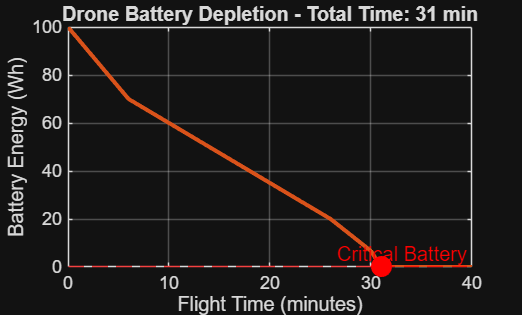

% Drone Battery and Flight Time (Aerospace / Robotics) 
% Define Battery Life and Power Parameters
battery_capacity = 100; % Total energy in Watt-hours
dt = 1;                 % Time step in minutes 
t = 0:dt:40;            % Time vector (up to 40 minutes)

% Power consumption (Watts) for different modes
p_hover  = 200; 
p_cruise = 150; 
p_ascent = 300; 

% Model of Energy Depletion
% Simulation: 5 min ascent, 20 min cruise, then hover
current_energy = battery_capacity; % Start full
energy_history = zeros(size(t));   % Array to track energy

for i = 1:length(t)
    % Store current energy level
    energy_history(i) = current_energy;
    
    % Determine power draw based on time (flight mode)
    if t(i) <= 5
        power_draw = p_ascent; % Power_draw means the total amount drawn from battery capacity and linked to ascent 
    elseif t(i) <= 25
        power_draw = p_cruise; % Power_draw means the total amount drawn from battery capacity and linked to cruising 
    else
        power_draw = p_hover; % Power_draw means the total amount drawn from battery capacity and linked to hovering
    end
    
    % Energy used = Power * Time. Since dt is in minutes, divide by 60 for Wh.
    current_energy = current_energy - (power_draw * (dt/60));
    
    % Stop the simulation if battery hits 0
    if current_energy <= 0
        energy_history(i:end) = 0; % Battery is dead
        flight_time = t(i);
        break;
    end
end

%% 3. Visualization
figure;
plot(t, energy_history, 'LineWidth', 2, 'Color', [0.85 0.32 0.1]); %Plots the energy line
grid on; % Allows for a grid 
hold on; % Lines 42 to 52 all work together, they are combined 

% Mark the end of flight
yline(0, 'r--', 'Critical Battery'); % Shows a line to display the battery has depleted 
plot(flight_time, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % plots flight time 
xlabel('Flight Time (minutes)'); % Labels the x axis as Flight Time 
ylabel('Battery Energy (Wh)'); % Labels the y axis as Battery Energy
title(['Drone Battery Depletion - Total Time: ', num2str(flight_time), ' min']); % Displays a title on the graph 